# Tina Höflich, Vorname 2 Name2

## Fahrzeugdaten laden

FzgDaten;

FzgDaten geladen


## Längsdynamik

9.1.1

## Bremsvorgang

Bremsvorgang simulieren

ax_1 = -1;
ax_2 = -9;
T0 = 0.6;
T1 = 0.3;
T2 = 0.2;
model = 'Bremsvorgang';
load_system(model)
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
repeating_sequence = [0 T0 T0+T1 T0+T1+T2 20];
repeating_sequence_out = [0 0 ax_1 ax_2 ax_2];

out = sim(simIn);

Daten auslesen

outputs = out.yout;
t = out.tout;
s = outputs{1}.Values.Data;
v = outputs{2}.Values.Data;

a = outputs{3}.Values.Data;

Beschleunigung darstellen

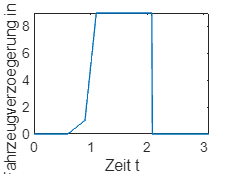

plot(t,-a)
xlabel("Zeit t")
ylabel("Fahrzeugverzoegerung in m/s2")
ylim([min(-a), max(-a)])
xlim([min(t), max(t)])

Geschwindigkeit darstellen

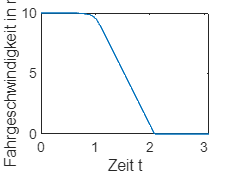

plot(t,v)
xlabel("Zeit t")
ylabel("Fahrgeschwindigkeit in m/s")
ylim([min(v), max(v)])
xlim([min(t), max(t)])

Strecke darstellen

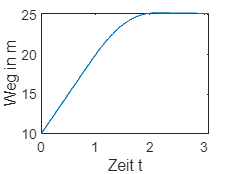

plot(t,s)
xlabel("Zeit t")
ylabel("Weg in m")
ylim([min(s), max(s)])
xlim([min(t), max(t)])

### 9.1.2 Tangentialkraftdiagramm

clf;

model = 'Tangentialkraftverteilung';
load_system(model);
simIn = Simulink.SimulationInput(model);
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01');
out = sim(simIn);

Outputs des Simulink Models laden

outputs = out.yout;
psi = outputs{1}.Values.Data;
chi = outputs{2}.Values.Data;
FBh = outputs{3}.Values.Data;
FBv = outputs{4}.Values.Data;


Berechnen der Linien konstanter Abbremsung

Ay = -(1-psi)/chi;
Bx = psi/chi;
figure;
hold on;
for z = 0:0.2:1.0
    x = linspace(0, z);
    y = -1 * x + z;
    line(x, y, 'Color', 'r')
end


Berechnen der Charakteristische Linienscharen der Reibungszahlen

for my = 0.6:0.2:1.0
    z = my;
    x = my * (1-psi + z * chi);
    y = my * (psi - z*chi);

    line([0 x], [Ay, y], 'Color','g')
    line([x Bx], [y, 0],'Color', 'g')
end


Plotten der Linie einer Installierten Festabstimmung

plot(FBv, FBh,'b');


 Beschriftungen

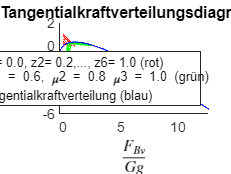


title('Tangentialkraftverteilungsdiagramm');
legend({'z1 = 0.0, z2= 0.2,..., z6= 1.0 (rot)', ...
       ' \mu1 = 0.6, \mu2 = 0.8 \mu3 = 1.0 (grün)', ...
       'Tangentialkraftverteilung (blau)'},Location="southeast")
xlabel('$\frac{F_{Bv}}{Gg}$','Interpreter','latex');
ylabel('$\frac{F{Bh}}{G_g}$','Interpreter','latex');

## Querdynamik

### 9.2.1 Lineare Übertragungsfunktion

Ch_stern  = Ch / Fnh

Ch_stern = 20.5518

Cv_stern = Cv / Fnv

Cv_stern = 9.4854

Berechnung des Eigenlenkgradient EG

EG = 1 / (g * Cv_stern) - 1 / (g * Ch_stern)

EG = 0.0058

Berechnung des Schwimmwinkelgradient SG

SG = 1 / (g * Ch_stern)

SG = 0.0050


v = 60 / 3.6 % m/s

v = 16.6667

Berechnung der Zählerzeitkonstante

Tz = v * SG

Tz = 0.0827

Berechnung der Abklingkonstante

abklingkonstante = (m * (Cv * Lv * Lv + Ch * Lh) + J * (Cv + Ch)) / (J * m * v)

abklingkonstante = 16.2927

sigma = abklingkonstante / 2

sigma = 8.1464

Berechnung der ungedämpfte Eigenfrequenz

Eigenfrequenz = (m*v^2*(Ch * Lh - Cv * Lv) + Cv * Ch * L^2)/ (J  * m * v^2)

Eigenfrequenz = 115.1613

omega_0 = sqrt(Eigenfrequenz)

omega_0 = 10.7313

Berechnung der stationäre Gierverstärkung


gierverstaerkung = (Cv * Ch * L) / (J * m * v * Eigenfrequenz)

gierverstaerkung = 3.7815

Berechnung des Dämpfungsmaß

daempfungsmass = sigma / omega_0

daempfungsmass = 0.7591

#### Plot über die Geschwindigkeit

Formeln neu berechnen mit fortlaufender Geschwindigkeit 

v_kmh = linspace(0,250,251);
v = v_kmh ./ 3.6;
Tz = v .* SG;
abklingkonstante = (m * (Cv * Lv * Lv + Ch * Lh.^2) + J * (Cv + Ch)) ./ (J * m * v); 
sigma = abklingkonstante / 2;
Eigenfrequenz = (m .* v.^2 *(Ch * Lh - Cv * Lv) + Cv * Ch * L^2) ./ (J  * m .* v.^2);
gierverstaerkung = (Cv * Ch * L) ./ ( J .* m .* v .* Eigenfrequenz); % K/w_0^2)
omega_0 = sqrt(Eigenfrequenz);
daempfungsmass = sigma ./ omega_0;

Berechnung der ungedämpfte Eigenfrequenz mit fortlaufender Geschwindigkeit

v_0 = omega_0 / (2 * pi); % ni0

Berechnung der gedämpfte Eigenfrequenz mit fortlaufender Geschwindigkeit

v_g = v_0 .* sqrt(1-(daempfungsmass.^2)); %ni_ret

#### Plot der ungedämpften Eigenfrequenz 

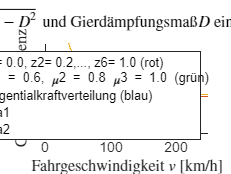

xindex = find(real(v_g) > 0);

plot(real(v_kmh(xindex-1:250)), real(v_g(xindex-1:250)));
hold on 
plot(real(v_kmh(xindex-1:250)), real(v_0(xindex-1:250))) ;
xlim([0 250]); 
ylim([0 2.5]); 
ylabel("Giereigenfrequenz", "Interpreter", "latex") 
xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex") 
title (['Giereigenfreq. $v_0 = \frac{\omega_0}{2\pi}, v = \frac{\omega}{2\pi} = \frac{\omega_0}{\pi}\sqrt{1-D^2}$' ... 
    ' und Gierd\"ampfungsma\ss $D$ eines Fahrzeuges \"uber der Fahrgeschwindigkeit'] , 'Interpreter','latex') 
hold off 

#### Plot des Gierdämpfungsmaß :

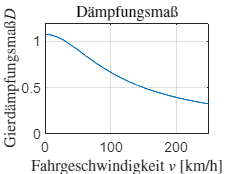


figure
plot(v_kmh, daempfungsmass)
xlim([0 250]);
title('D\"ampfungsma\ss', 'Interpreter','latex') ;

xlabel("Fahrgeschwindigkeit $v$ [km/h]", "Interpreter", "latex");
ylabel('Gierd\"ampfungsma\ss $D$', "Interpreter", "latex");
ylim([0 1.2]);
grid

### 9.2.2 Lenkradwinkelsprung  

#### Sprungantwort: von G(s)= 𝜓(𝑠)/ 𝛿(𝑠) 

unter Verwendung der Parameter

Berechnung von $G(s) = \frac{\dot{\psi}(s)}{\delta(s)} = K \cdot \frac{1 + T_zs}{s^2+2\sigma s + \omega_0^2}$

v = 60 * 3.6;
Tz = v ./ SG;

tf_gs = tf([ K*Tz K ] , [1  2*sigma Eigenfrequenz]);

Visaualisierung des Bode DIagramm von G(S)

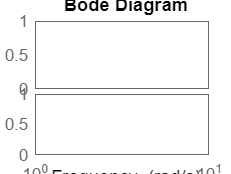

bode(tf_gs)

Berechnung der Sprungantwort :

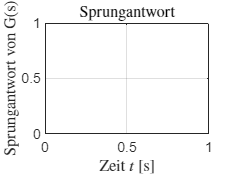

config = RespConfig('Amplitude', 45/iS);
[y_out, t_out] = step(tf_gs, 1.0, config);
figure; % Create a new figure
plot(t_out, y_out); % Plot the step response

% Add title and labels
title('Sprungantwort', 'Interpreter','latex') ;
xlabel("Zeit $t$ [s]", "Interpreter", "latex");
ylabel(" Sprungantwort von G(s)", "Interpreter", "latex");

% Show grid
grid on;

#### Nichtlineares Einspurmodell  

model = 'Lenkradwinkelsprung';
load_system(model)
simIn = Simulink.SimulationInput(model);

*Hinweis: Alle Modellparameter, die mit *setModelParameter() *gesetzt werden können, lassen sich folgendermaßen ermitteln:*

Konfiguration der Simulation: $t_\text{Start}=0$, $t_\text{Stop}=t_{\rm end}$, Integration mit fester Zeitschrittweite $\Delta t=0.01$  

tend = 1;
simIn = setModelParameter(simIn,...
    'SolverType','Fixed-step',...
    'FixedStep','0.01',...
    'StartTime','0',...
    'StopTime',num2str(tend));

Konfiguration des Lenkradwinkelsprungs mit $\delta_\text{H}=45\degree $ und $v=60\text{ km/h}$

dH = 45;
v = 60;
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","Time",'0');         % Sprung bei t=0
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/dH","After",string(dH)); % Sprunghöhe in Grad
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/v","Value",string(v));   % Konstante Geschwindigkeit in km/h

Konfiguration der Pacejka-Blöcke mit den Schräglaufsteifikgeiten $C_\text v$, $C_\text h$ und den Achslasten $F_\text{nv}$, $F_\text{nh}$

simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Cv", "Value",string(Cv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Ch", "Value",string(Ch));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnv","Value",string(Fnv));
simIn = setBlockParameter(simIn,"Lenkradwinkelsprung/Einspurmodell/Reifenkräfte/Fnh","Value",string(Fnh));
applyToModel(simIn) % nicht unbedingt notwendig

Lenkradwinkelsprung simulieren

out = sim(simIn);

Daten auslesen

outputs = out.yout;
outputPsip = getElement(outputs,'psip');
t    = outputPsip.Values.Time;
psip = outputPsip.Values.Data;

Darstellung der Giergeschwindigkeit $\dot\psi$ über $t$ des nichtlinearen und des linearen Einspurmodells 

plot(t,psip)
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$\dot{\psi}$ $[^\circ/s]$','interpreter','latex')
title (['Lenkradwinkelsprung mit $\delta_{\rm H} = $' num2str(dH) '$^\circ$ und $v =$ ' num2str(v) ' km/h'] , 'Interpreter','latex'  )
legend('Nichtlinear','Linear','Location','southeast')

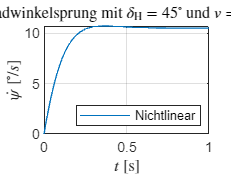

grid